V_rated = 12; 
w_free = 300;            %rev/min
w_free = w_free*2*pi/60; %rad/s
u = symunit;
TauStall = 2.220; %kg-cm
TauStall = TauStall*double(unitConversionFactor(u.kgf*u.cm,u.Nm)); %N-m
k = V_rated/w_free; %V-s (or N-m/A)clear
R = V_rated*k/TauStall; %Ohm
V_battery = 3.7; %Volts
TauMax = 0.3*V_battery*k/R %Do not exceed 30% of the stall torque

TauMax = 0.0201

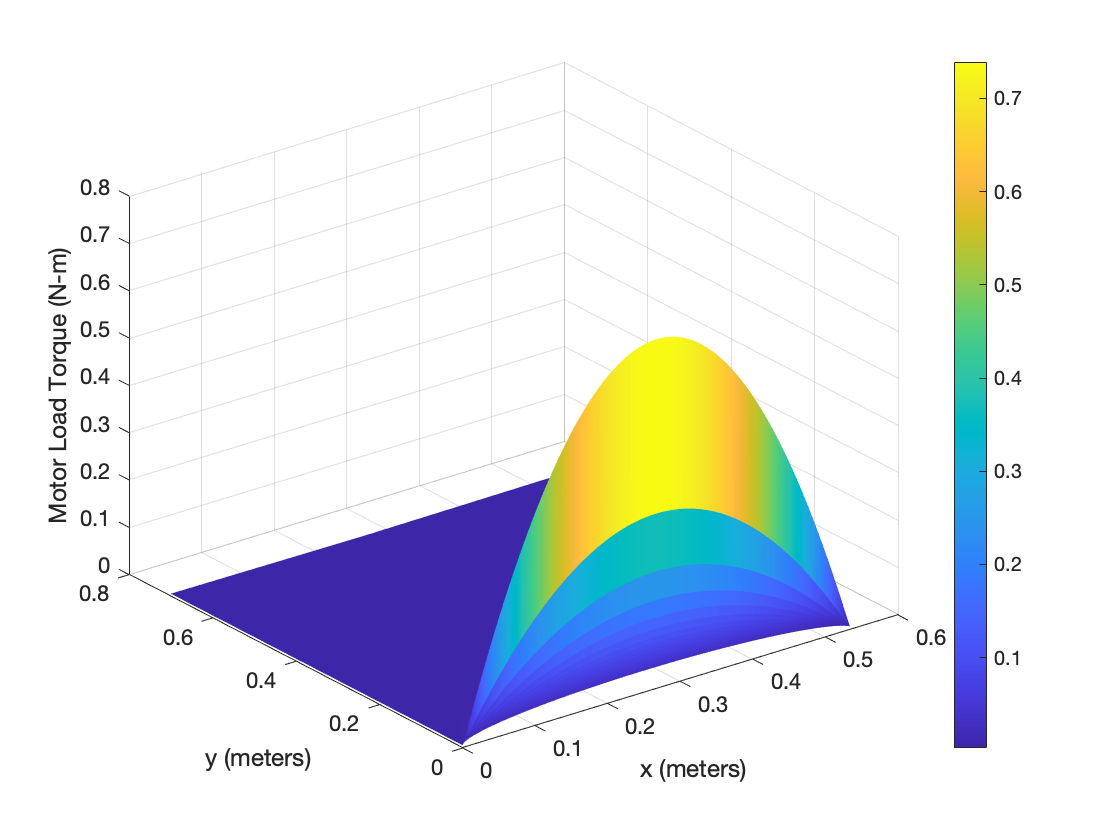



Base = 0.535;
H_board = 0.7;
xarray = 0:0.001:Base;
yarray = 0.001:0.001:H_board;

[X,Y] = meshgrid(xarray,yarray);

r_spool = 0.0045;   %m
Mass = 0.25;       %kg (You can modify this based on the actual weight of your robot.)
Weight = Mass*9.81; %N

theta1 = atan(X./Y);
theta2 = atan((Base-X)./Y);

F1 = Weight*sin(theta2)./(sin(theta1).*cos(theta2) + sin(theta2).*cos(theta1));
F2 = Weight*sin(theta1)./(sin(theta1).*cos(theta2) + sin(theta2).*cos(theta1));

T1 = F1/2;
T2 = F2/2;

Tau1 = T1*r_spool;
Tau2 = T2*r_spool;

Tau = max(Tau1,Tau2);

surf(X,Y,Tau,'EdgeColor','none')
xlabel('x (meters)')
ylabel('y (meters)')
zlabel('Motor Load Torque (N-m)')
colorbar

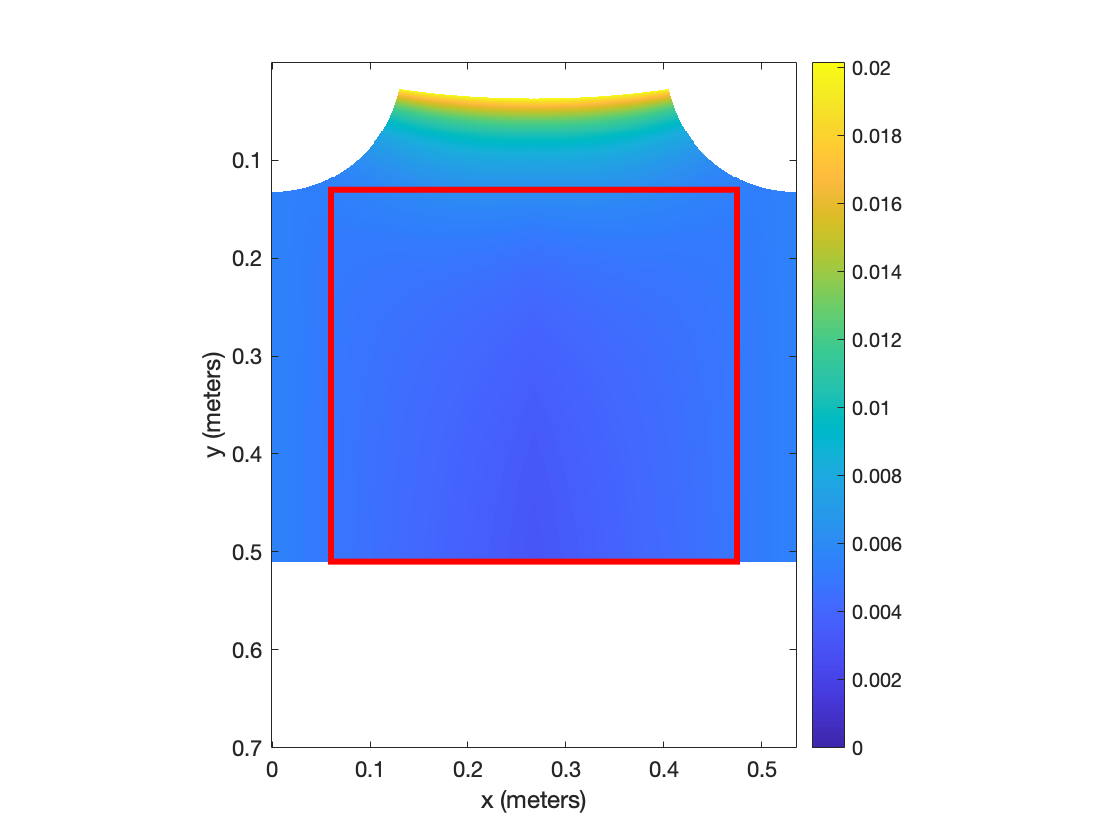


pulleyBuffer = 0.05; %Minimum distance to pulley (meters)
L_arm = 0.075;       %meters
H_robot = 0.19;      %meters
r_pulley = 0.0075;   %meters

opacity = ones(size(X));
opacity(Tau > TauMax) = 0;

nearLeftPulley = X.^2 + Y.^2 <= (L_arm + r_pulley + pulleyBuffer).^2;
nearRightPulley = (Base-X).^2 + Y.^2 <= (L_arm + r_pulley + pulleyBuffer).^2;
opacity(nearLeftPulley | nearRightPulley) = 0;

nearBottom = Y > H_board - H_robot;
opacity(nearBottom) = 0;

imagesc(xarray,yarray,Tau,'AlphaData',opacity)
xlabel('x (meters)')
ylabel('y (meters)')
colorbar
ax = gca;
ax.CLim = [0 TauMax];
ax.XLim = [0 Base];
ax.YLim = [0 H_board];
axis equal tight
pickedX = 0.06; %Change this to your chosen minimum x-value (meters)
pickedY = 0.13; %Change this to your chosen minimum y-value (meters)
xLim = [pickedX Base-pickedX];
yLim = [pickedY H_board-H_robot];
hold on
rectangle('Position',[xLim(1) yLim(1) diff(xLim) diff(yLim)],...
    'EdgeColor','red','LineWidth',3)
hold off